# **  PREPROCESSING WORKFLOW FOR *****BRECAHAD (2019)***

***This work focuses on the development of a breast cancer object detector based on machine learning algorithms. The implementation of this technology aims to improve the efficiency and accuracy of diagnosis, allowing faster and more reliable identification of cellular abnormalities associated with breast cancer. The dataset used for this task is BreCaHad (2019).***

** *NOTE: This script contains the execution of functions contained in the same folder, they can be opened to consult their operation or call the 'help function' command to obtain a brief description of the function (e.g. 'help Labelling').**

##  CODE DEVELOPMENT

-----------------------------------------------------------------------------------------------------------------------------------------------------------------------

## ` 1.Initialisation`

We reset all the variables, delete the figures and clean the MATLAB terminal so that the code runs cleanly and without overwriting variables.

%% Variable reseting
 clear all
 close all
 clc

-----------------------------------------------------------------------------------------------------------------------------------------------------------------------

## `2. Rescaling of images`

* Because we are going to train our network with pre-trained architectures, we must accommodate our Dataset to be compatible with them. The first step is to rescale all the original images of the dataset to the desired size using the 'ImageResizer' function. *

 

% Path of the folder with the original images (User-defined)
inputFolder = 'BreCaHad_Dataset\BreCaHad\images'; 

% Destination folder path for the resized images (User defined)
outputFolder = 'BreCaHad_Dataset\BreCaHad\images_resized';

% Desired size for the resized images
targetSize = [640, 640];

ImageResizer(inputFolder,outputFolder,targetSize)


-----------------------------------------------------------------------------------------------------------------------------------------------------------------------

## `3. Importing and creating the image DataStore`

*To train automatic classifiers on images, Matlab works with objects known as ImageDatastores, so we must create one and, in turn, extract the GroundTruth relative to each image (which are in JSON format). In this project, we will use the whole BreCaHad dataset as training and we will test altered images to check the performance of the classifier.*

 

% Specifies the path to the directory containing the images
% resized images
ruta_dir = outputFolder;

% Path to the directory containing the JSON annotation files
dir_anots = 'BreCaHad_Dataset\BreCaHad\groundTruth';

% Create the ImageDatastore with the function 'CreateAnnotatedDatastore'.
[imds,anots]= CrearDatastoreAnotado(ruta_dir,dir_anots);

Anotaciones para la imagen Case_1-01.json:
Anotaciones para la imagen Case_1-02.json:
Anotaciones para la imagen Case_1-03.json:
Anotaciones para la imagen Case_1-04.json:
Anotaciones para la imagen Case_1-05.json:
Anotaciones para la imagen Case_1-06.json:
Anotaciones para la imagen Case_1-07.json:
Anotaciones para la imagen Case_1-08.json:
Anotaciones para la imagen Case_10-01.json:
Anotaciones para la imagen Case_10-02.json:
Anotaciones para la imagen Case_10-03.json:
Anotaciones para la imagen Case_10-04.json:
Anotaciones para la imagen Case_10-05.json:
Anotaciones para la imagen Case_10-06.json:
Anotaciones para la imagen Case_10-07.json:
Anotaciones para la imagen Case_10-08.json:
Anotaciones para la imagen Case_10-09.json:
Anotaciones para la imagen Case_10-10.json:
Anotaciones para la imagen Case_11-07.json:
Anotaciones para la imagen Case_11-09.json:
Anotaciones para la imagen Case_11-10.json:
Anotaciones para la imagen Case_11-11.json:
Anotaciones para la imagen Case_11-12.js

-----------------------------------------------------------------------------------------------------------------------------------------------------------------------

## `4. Labeling`

*We have already decoded the GroundTruths and obtained an ImageDatastore, but now it is necessary to link each response to each image; this process is known as labelling. With this procedure we will obtain the labelling data needed to train our model.*

 

%We define the classes of the labels
etiquetas = {'tumor' 'notumor' 'mitosis' 'apoptosis' 'lumen' 'nolumen'};

%We define the size of the training images for YOLO.
data_size=[targetSize, 3];

%Since we only have the centroids of each element of interest,
%we must generate BoundingBoxes around each element for the model to recognise objects across defined regions of the image.
%model recognises objects across defined regions of the image.

%The %roi_size, refers to the dimensions of the square in pixels considered
%around each centroid. Note that this can be customised for each
%class.

roi_size=[20 20 20 20 20 20];

%Define the empty directory where the tagged images are stored (now
%this is not used now as it would slow down the code a lot, but it can be
%can be used)

etiq_dir='BreCaHad_Dataset\BreCaHad\images_labeled'

etiq_dir = 'BreCaHad_Dataset\BreCaHad\images_labeled'

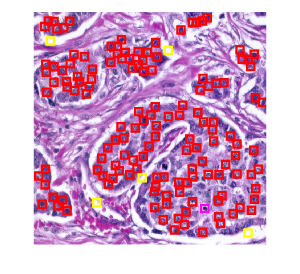


%Dataset is labeled

[labelData] = Etiquetado(imds,etiquetas,anots,data_size,roi_size,etiq_dir);

-----------------------------------------------------------------------------------------------------------------------------------------------------------------------

## `5. Training Data Configuration`

*Matlab works with its own type of variable 'GroundTruth', which is why the function 'GetGroundTruth' converts the labelling data into a format compatible with the training of the subsequent models. Finally, a training table is obtained where each image with its corresponding bounding boxes of each class can be intuitively observed.*

 

%Create the GroundTruth object type
[gTruth] = ObtenerGroundTruth(imds,labelData,etiquetas);

addpath('C:\Users\G532\Documents\MATLAB\Examples\R2023b\vision\ExportGroundTruthObjectToCustomAndCOCOJSONFilesExample')
exportGroundTruthToJSON(gTruth,'gTruth.json','COCO',true)

%We create the Training Data type object
trainingdataTable= objectDetectorTrainingData(gTruth);

Error using objectDetectorTrainingData
The input groundTruth object/s do not contain any valid object detector training data.


%Let's extract all the columns other than the images and create an object
%of type boxLabelDatastore
blds = boxLabelDatastore(trainingdataTable(:,2:end));

%We combine the dataset of images with the last one obtained to have a
%single dataset relating images-groundTruth
ds=combine(imds,blds);